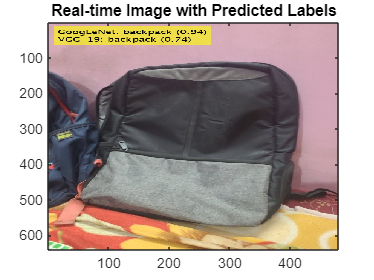

Unable to capture snapshot because camera is closed.

clc;
clear all;
m = mobiledev;
cam = m.camera('back');
[net1, classNames1] = imagePretrainedNetwork('googlenet');
[net2, classNames2] = imagePretrainedNetwork('vgg19');
h = figure;
saveDir = 'D:\matlab';
if ~exist(saveDir, 'dir')
    mkdir(saveDir);
end
imgCount = 1;

while ishandle(h)
    im = snapshot(cam, "manual");
    im1 = imresize(im, [224, 224]);
    im1 = single(im1);
    im2 = imresize(im, [224, 224]);
    im2 = single(im2);
    score1 = predict(net1, im1);
    score2 = predict(net2, im2);
    [maxScore1, idx1] = max(score1);
    [maxScore2, idx2] = max(score2);
    label1 = classNames1{idx1};
    label2 = classNames2{idx2};
    labelText = sprintf('GoogLeNet: %s (%.2f)\nVGG-19: %s (%.2f)', label1, maxScore1, label2, maxScore2);
    boxColor = 'yellow';
    textColor = 'black';
    fontSize = 18;
    labeledImage = insertText(im, position, labelText, 'FontSize', fontSize, 'BoxColor', boxColor, 'TextColor', textColor);
    image(labeledImage);
    title('Real-time Image with Predicted Labels');
    filename = sprintf('image_%d.jpg', imgCount);
    savePath = fullfile(saveDir, filename);
    imwrite(labeledImage, savePath);
    imgCount = imgCount + 1;
    drawnow;
end